## **Import data**

data = readmatrix('All data merged.xlsx')

data =    50.0000         0    0.1000    0.2000    0.2000    2.2977    0.1389    4.9632    0.0275    2.2656    0.1396    2.9920    0.2314    1.7879    1.0142
   50.0000         0    0.5950    0.2000    0.2000    2.3958    0.1308    4.9136    0.0274    2.3789    0.1306    2.9448    0.2309    1.8005    1.0071
   50.0000         0    1.0900    0.2000    0.2000    2.4870    0.1248    4.8669    0.0274    2.4798    0.1245    2.8995    0.2304    1.8132    1.0029
   50.0000         0    1.5850    0.2000    0.2000    2.5700    0.1204    4.8219    0.0273    2.5684    0.1204    2.8549    0.2300    1.8266    1.0006
   50.0000         0    2.0800    0.2000    0.2000    2.6449    0.1172    4.7776    0.0273    2.6460    0.1177    2.8102    0.2296    1.8407    0.9996
   50.0000         0    2.5750    0.2000    0.2000    2.7122    0.1148    4.7336    0.0273    2.7144    0.1158    2.7653    0.2292    1.8557    0.9992
   50.0000         0    3.0700    0.2000    0.2000    2.7728    0.1132    4.6895    0.0

x=data(:,1:5);
y=data(:,14:15);

## **Visualization of the data**

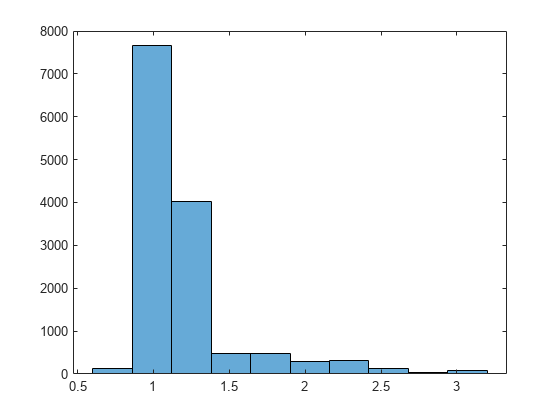

histogram(y(:,1),10);

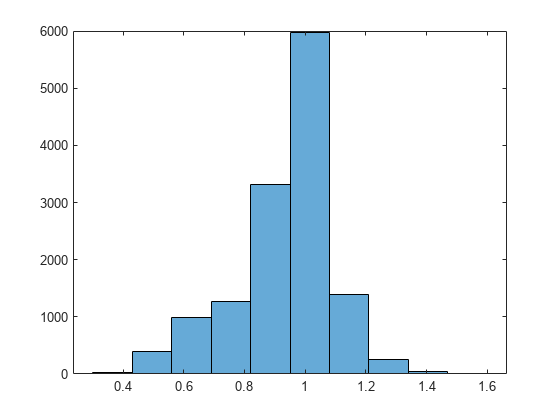

histogram(y(:,2),10);

## **Normalize Feature (using standard normalization)**

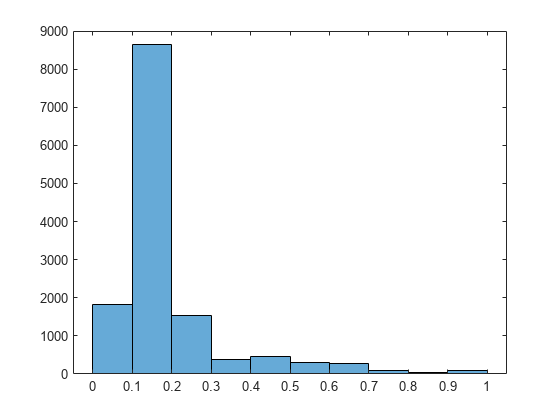

[x2,y2]=normalize_std(x,y);
histogram(y2(:,1),10)

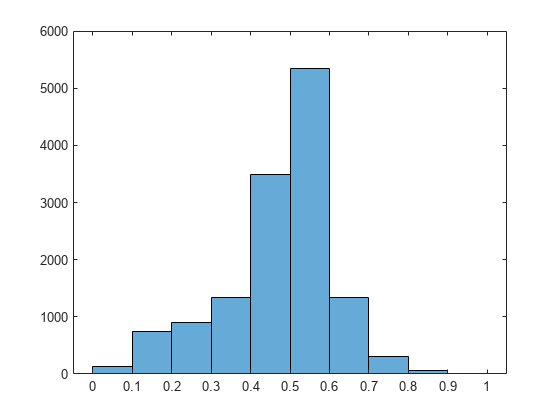

histogram(y2(:,2),10)

## **Data Split**

Index=(1:13650)';
[Training_index,Validation_index]=Split_data(Index);

## Separating Traning and Validation Set

data_normalized=cat(2,x2,y2);
training_set=data_normalized(Training_index,:);
validation_set=data_normalized(Validation_index,:);
training_input=training_set(:,1:5);
training_output=training_set(:,6:7);
validation_input=validation_set(:,1:5);
validation_output=validation_set(:,6:7);

# **Optimization**

%run to clear previous variable value
clear("rms_train_lm",'rms_val_lm','r2_train_lm',"r2_val_lm",'mape_train_lm',"mape_val_lm",'name','T_lm')

training_alg={'trainlm','trainbr','trainscg'};
n=4; %change hidden layer accordingly

n = 4

for ta=1:length(training_alg)
    for i=1:n
        tic
        %defining the architecture of the Ann
        hiddenLayerSize=i;
        lm=fitnet(hiddenLayerSize,training_alg{ta});
        
         %training of Ann
        [lm,tr_lm]=train(lm,training_input',training_output','useParallel','yes');
        T_lm{ta}(i,:)=toc;
    
        Y_lm=lm(training_input');
        Yt_lm=training_output';
        Yv_lm=lm(validation_input');
        Yvt_lm=validation_output';
    
        yTrain_lm=(Y_lm'.*(max(y)-min(y))+min(y))';
        yTrainTrue_lm=(Yt_lm'.*(max(y)-min(y))+min(y))';
        yVal_lm=(Yv_lm'.*(max(y)-min(y))+min(y))';
        yValTrue_lm=(Yvt_lm'.*(max(y)-min(y))+min(y))';
    
        %RMSE
        for j=1:2
            rms_train_lm{ta}(i,j)=sqrt(mean(((yTrain_lm(j,:)-yTrainTrue_lm(j,:)).^2),2));
        end   
        for j=1:2
            rms_val_lm{ta}(i,j)=sqrt(mean(((yVal_lm(j,:)-yValTrue_lm(j,:)).^2),2));
        end
        %R^2
        for j=1:2
            r2_train_lm{ta}(i,j)=1 - (sum(((yTrainTrue_lm(j,:) - yTrain_lm(j,:)).^2),2)/sum(((yTrainTrue_lm(j,:) - mean(yTrainTrue_lm(j,:),2)).^2),2));
        end   
        for j=1:2
            r2_val_lm{ta}(i,j)=1 - (sum(((yValTrue_lm(j,:) - yVal_lm(j,:)).^2),2)/sum(((yValTrue_lm(j,:) - mean(yValTrue_lm(j,:))).^2),2));
        end
        %MAPE
        for j=1:2
            mape_train_lm{ta}(i,j)=mean(abs((yTrainTrue_lm(j,:)-yTrain_lm(j,:))./yTrainTrue_lm(j,:)),2).*100;
        end   
        for j=1:2
            mape_val_lm{ta}(i,j)=mean(abs((yValTrue_lm(j,:)-yVal_lm(j,:))./yValTrue_lm(j,:)),2).*100;
        end
        
    end
end

## **Table**

for i=1:n
    name{i} = ['Hidden Layer size: ' num2str(i,'%d')];
end
for i=1:length(training_alg)  
    table_ann{i}=array2table([rms_val_lm{i},r2_val_lm{i},mape_val_lm{i},T_lm{i}],"VariableNames",{'ΔP/ΔPo(rmse)','ΔNu/ΔNuo(rmse)','ΔP/ΔPo(R2)','ΔNu/ΔNuo(R2)','ΔP/ΔPo(mape)','ΔNu/ΔNuo(mape)','Elapsed Time'});
    table_ann{i}=cat(2,name',table_ann{i});
end

# **Which algorithm is better among all**

## **Best hidden layer number for All**

bol=[];
clear ("index")
for i=1:length(training_alg) 
    anns=sum(table2array(table_ann{i}(:,4:5)),2);
    [junk, index{i}] = max(anns(:,1));
    temp=table_ann{i}(index{i},2:7);
    bol=cat(1,bol,temp);
end
var=table(index','VariableNames',{'Best hidden layer'});
bol=cat(2,training_alg',var,bol)

bol = 3×8 table
        Var1        Best hidden layer    ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)    ΔP/ΔPo(R2)    ΔNu/ΔNuo(R2)    ΔP/ΔPo(mape)    ΔNu/ΔNuo(mape)
    ____________    _________________    ____________    ______________    __________    ____________    ____________    ______________

    {'trainlm' }          {[4]}            0.11373          0.095624        0.88603        0.62958          7.0638           7.7237    
    {'trainbr' }          {[4]}            0.10698          0.097729        0.89915        0.61309          6.0171           7.8212    
    {'trainscg'}          {[4]}            0.11148            0.1037        0.89049        0.56436          6.5414           8.6266    


## Best algorithm overall and its hidden layer number

best=sum(table2array(bol(:,4:5)),2);
[junk, index] = max(best(:,1));
best=bol(index,:)

best = 1×8 table
       Var1        Best hidden layer    ΔP/ΔPo(rmse)    ΔNu/ΔNuo(rmse)    ΔP/ΔPo(R2)    ΔNu/ΔNuo(R2)    ΔP/ΔPo(mape)    ΔNu/ΔNuo(mape)
    ___________    _________________    ____________    ______________    __________    ____________    ____________    ______________

    {'trainbr'}          {[4]}            0.10698          0.097729        0.89915        0.61309          6.0171           7.8212    


# **Visualization**

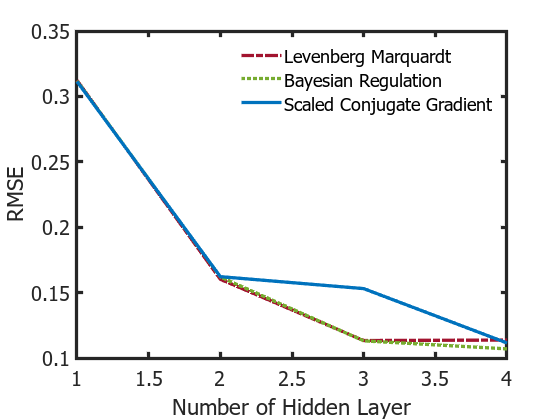

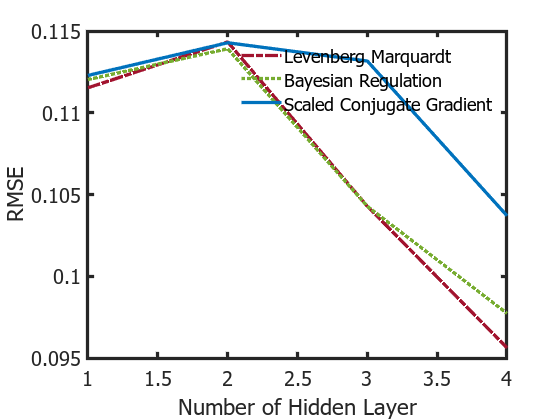

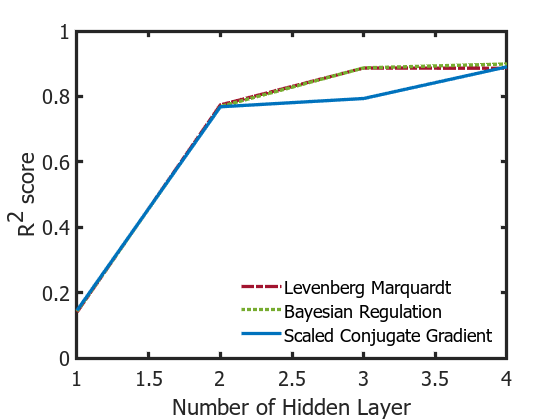

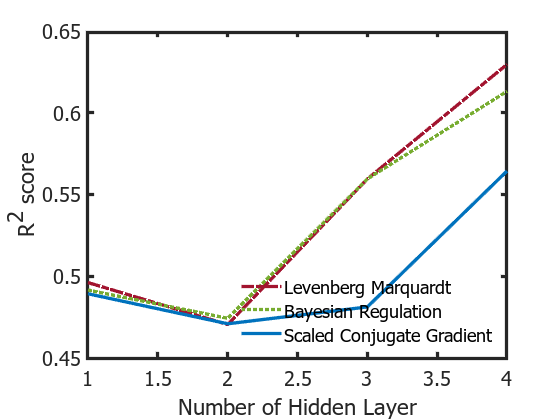

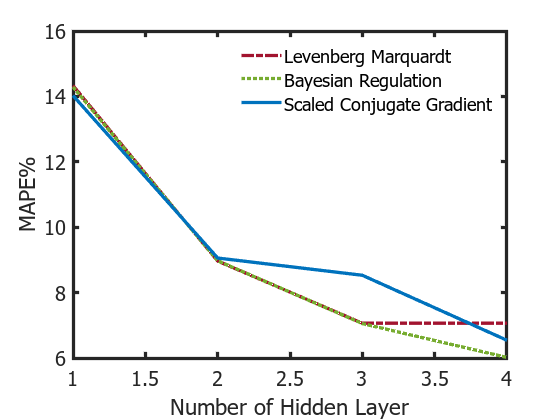

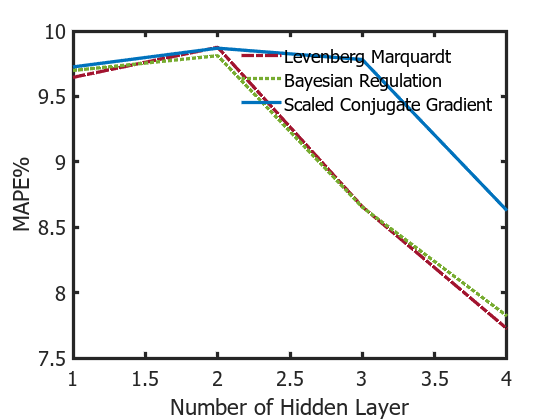

ylb=["RMSE","R^2 score","MAPE%"];
output=["ΔP÷ΔPo","ΔNu÷ΔNuo"];
style={'-.',':','-'};
for i=2:2:6    
    for j=i:i+1
        figure()
        SetfigureDefaults()
        box on;
        hold on;
        for k=1:length(table_ann)
            plot(1:n,table2array(table_ann{k}(:,j)),"LineStyle",style{k});        
        end
        hold off;
        xlabel('Number of Hidden Layer')
        ylabel(ylb(i/2))
        % title('ΔP/ΔPo')
        if i==4
            legend('Levenberg Marquardt','Bayesian Regulation','Scaled Conjugate Gradient',"Box","off",'Location','southeast');
        else
            legend('Levenberg Marquardt','Bayesian Regulation','Scaled Conjugate Gradient',"Box","off",'Location','northeast');
        end
        
        Plot_rmse=sprintf('Your Directory/%s_optimisation(%s).jpg',output(j-i+1),ylb(i/2));
        % exportgraphics(gcf,Plot_rmse) 
    end
end

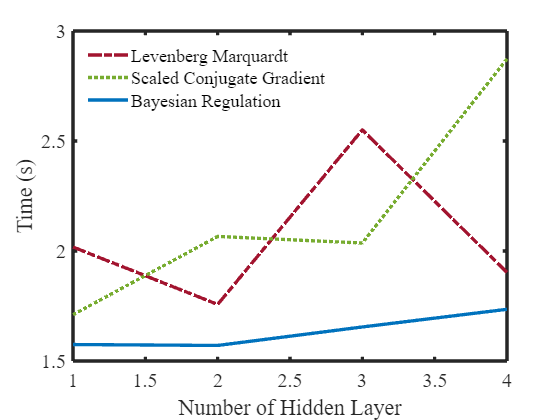

figure();
box on;
hold on;
SetfigureDefaults()
for k=1:length(table_ann)
    plot(1:n,table2array(table_ann{k}(:,8)),"LineStyle",style{k});        
end
xlabel('Number of Hidden Layer')
ylabel('Time (s)')
legend('Levenberg Marquardt','Scaled Conjugate Gradient','Bayesian Regulation',"Box","off",'location','northwest');hold off;
Plot_time=sprintf('D:/Matlab Drive/research/Figure/All Algorithm optimization comparison (new)/Time.jpg');
hold off

% exportgraphics(gcf,Plot_time)
